function egh444_group11(garfieldDataFile, pathToImages, searchStr)

EGH444 2019 Semester 2, Group 11, Final Project

Group members:

Name    Student No. 

Michael Irvine 1143701 

Paul Zapotezny-Anderson 4337948 

(Hector) Leonardo Villamil Dominguez 10411526

Input arguments: garfieldDataFile File name containing Garfield's colour range pathToImages Path to folder containing images searchStr Search string for matching files, e.g. '*_tr.png'

Output arguments: outputImages Cell array of output images

File outputs File containing processed output image. The file format will be the same as the input file. If the original file name is, 'original.ext', the output file name will be 'original_out.ext.

Instructions Add the path to the code to the MATLAB path, e.g. 'addpath ../path_to_code'. Run the function from the folder where output files are to be written. Specify the location of the input files using the pathToImages input argument.

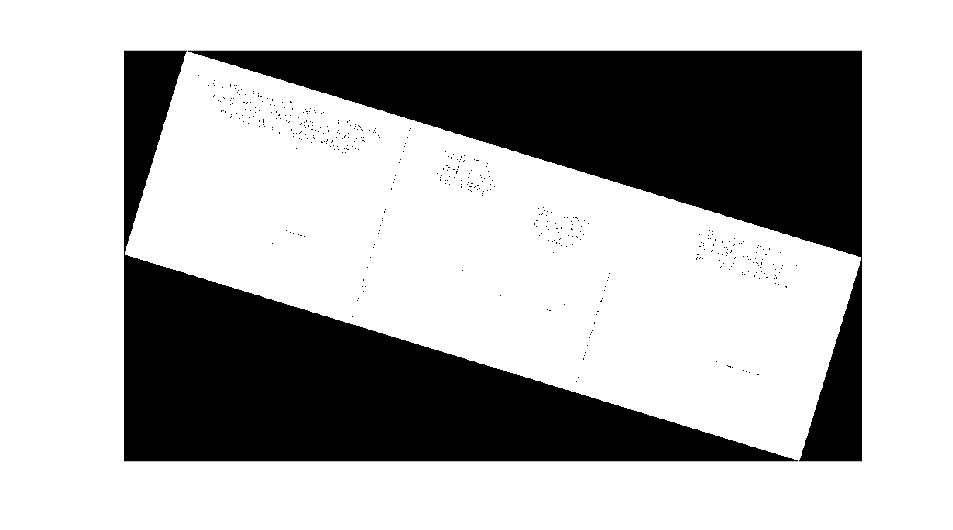

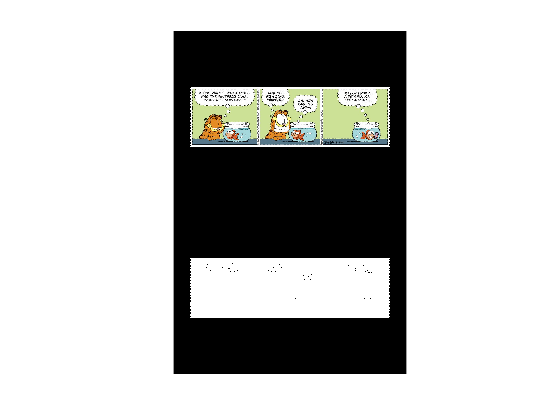

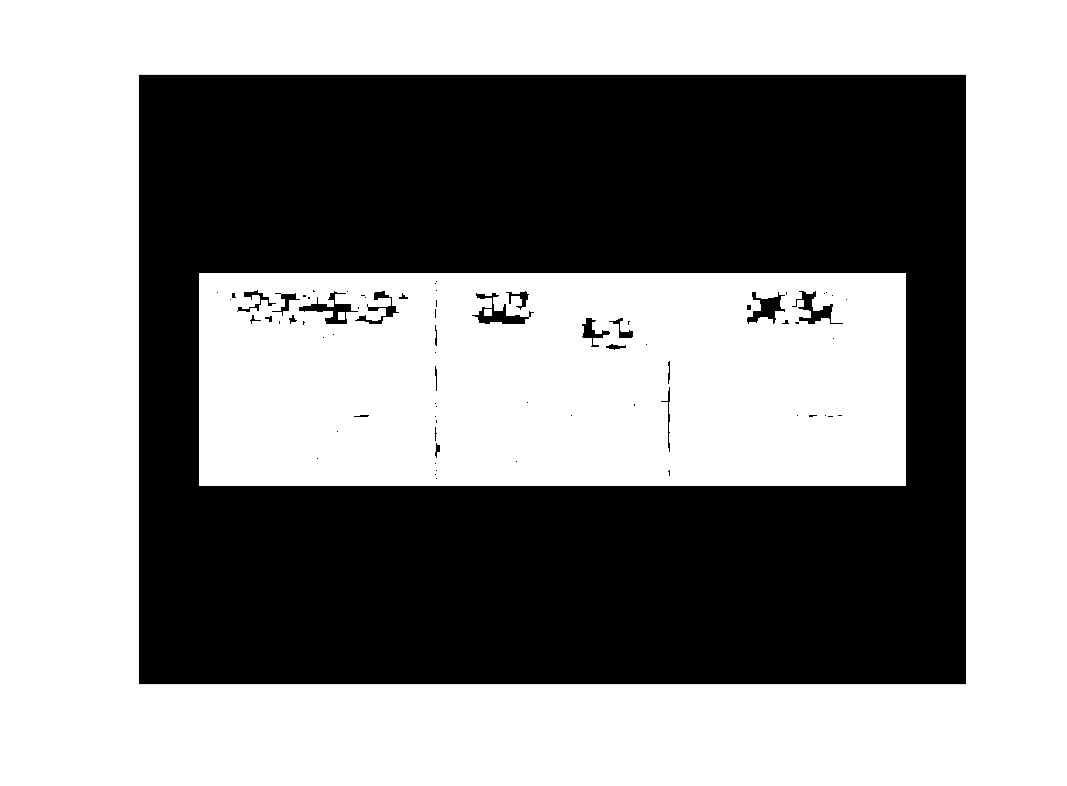

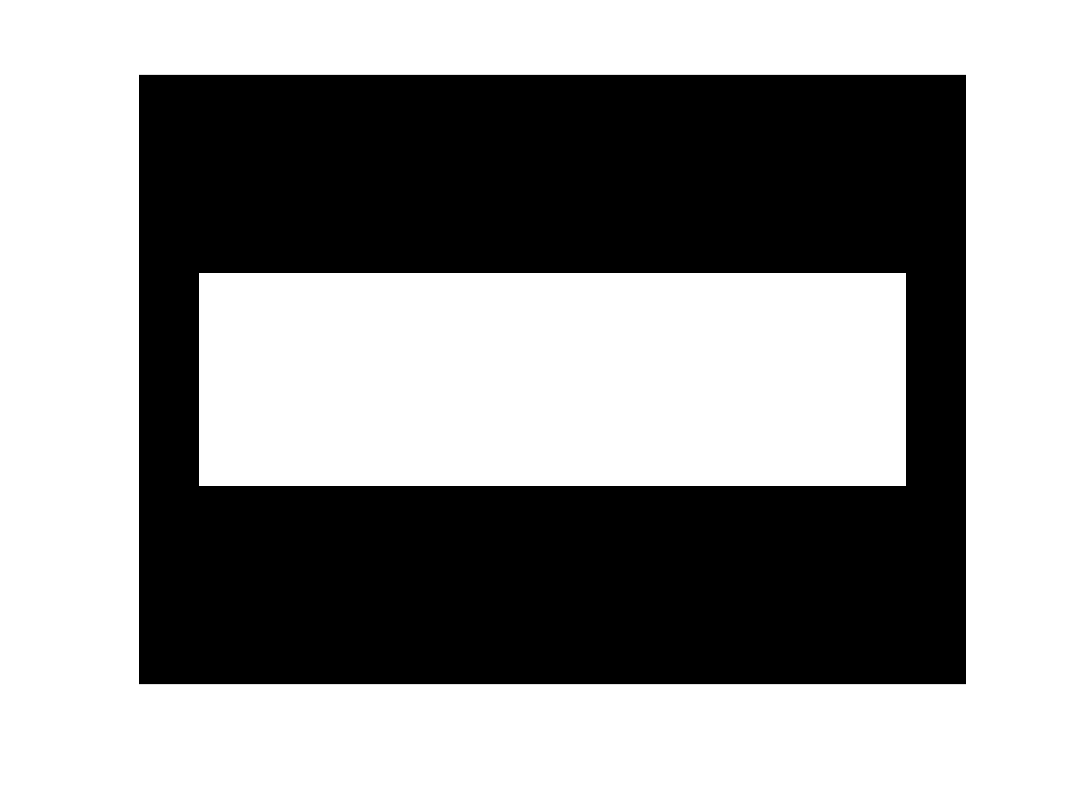

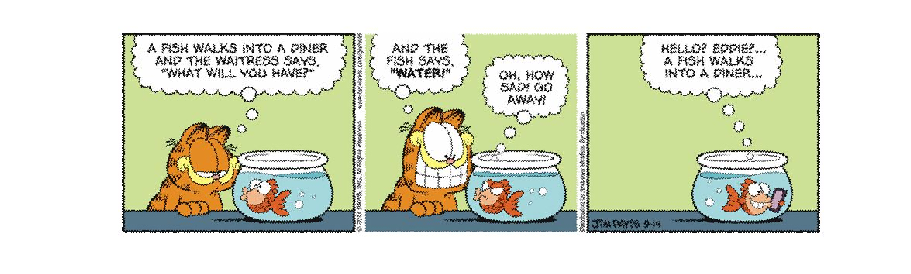

% function outputImages=egh444_group11(garfieldDataFile, pathToImages, searchStr)
clear
addpath ../ % release folder

% Load Garfield training data from file; the file must be in the search path
% File must have RGB colours in order
garfieldColour=csvread('garfield_training_data.csv');

% Read images from the specified folder matching the search string
[inputImages, fileNames] = read_images('../../GAR_datasets/\GAR_train', 'GAR_tr06.png');

% Create cell array to hold rotated images
rotatedImages=cell(size(inputImages));

% Set the image to process here
imageNumber=1;

% Rotate input image to horizontal
rotate_image_ls;

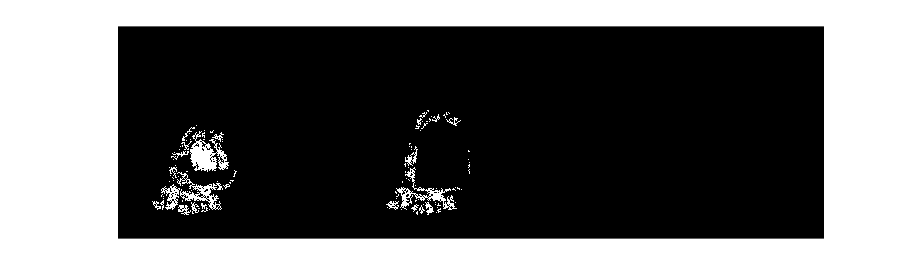

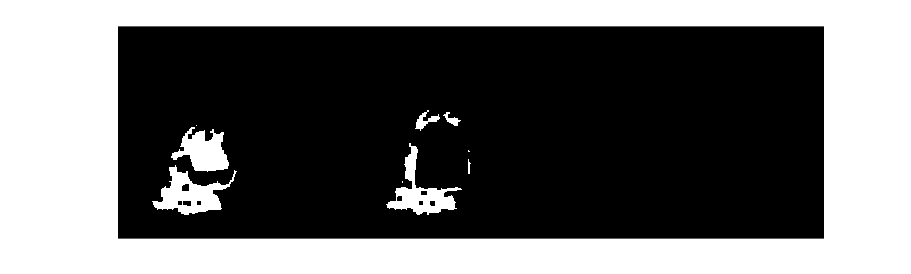

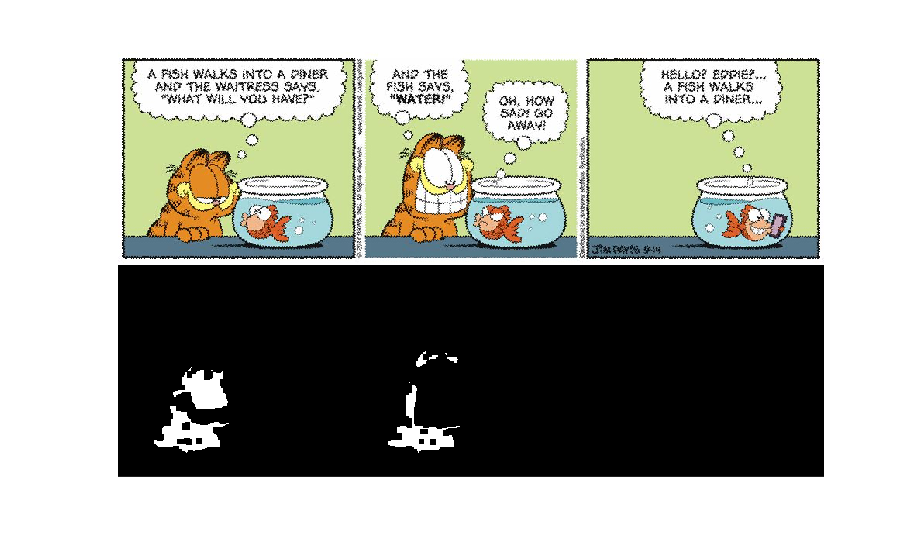


% Detect locations where Garfield exists
detect_garfield_ls;

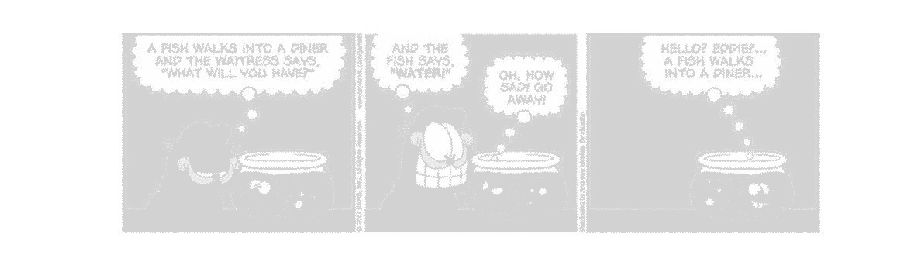

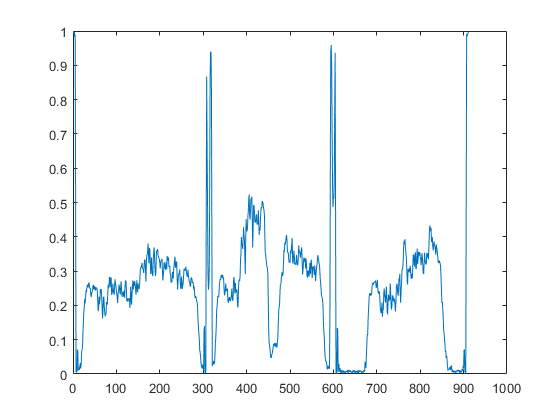

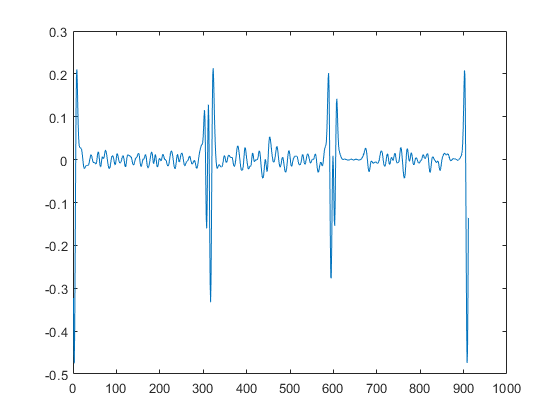

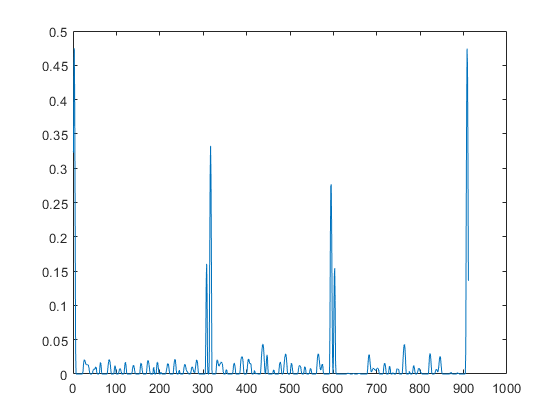

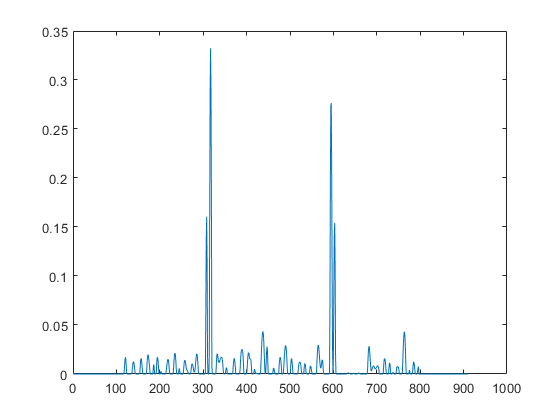

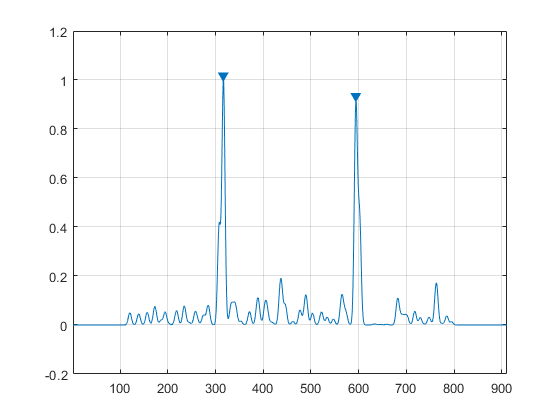

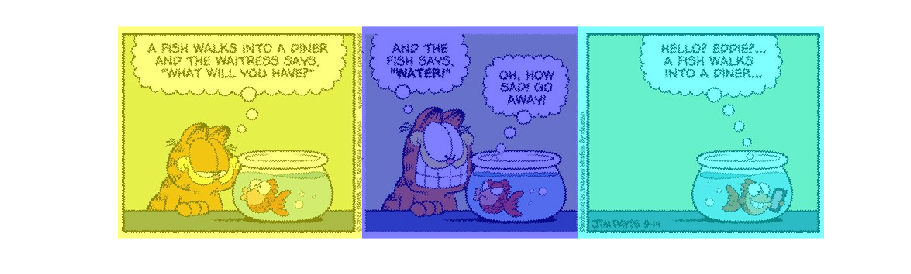


% Create mask of frames
mask_frames_ls;

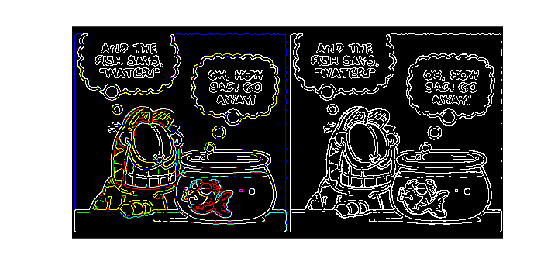

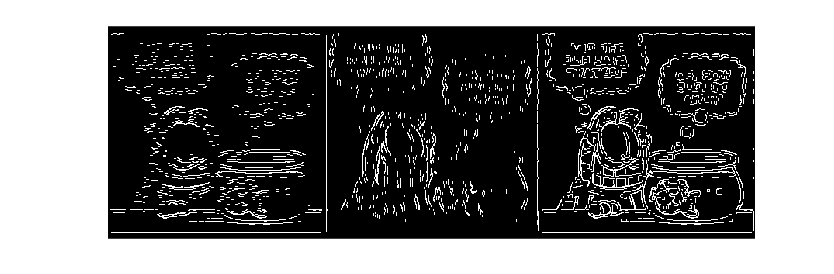

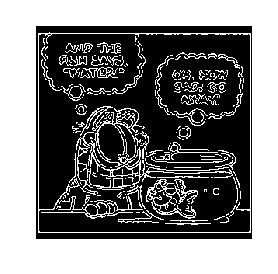

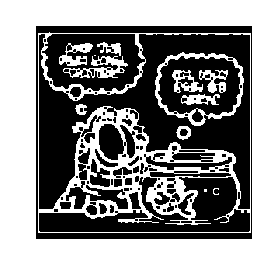

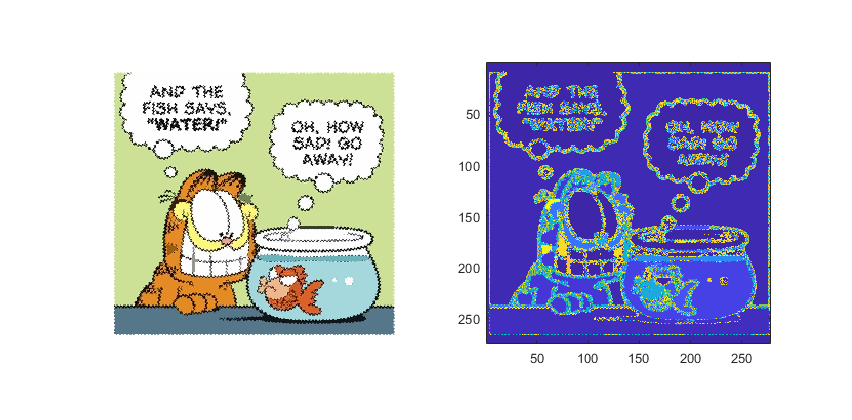

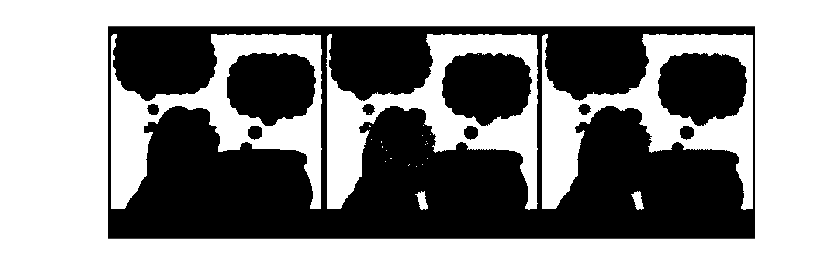

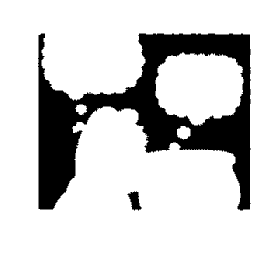

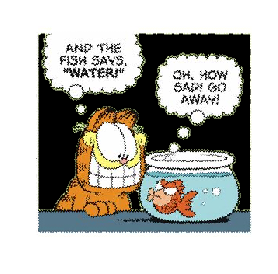


% Split images into frames, and paint background black
% [Let this run in a loop so it does the whole strip
% call blacken_background_ls later]
outputImages=rotatedImages;

for s=1:frameMask(end)

    % Create a mask for this frame
    thisFrame=frameMask==s;
    
    % Check for Garfield in this frame
    if any(thisFrame&garfieldMask,'all')
        % Find the column range for this frame
        frameRange=(frameEdges(s)+1):frameEdges(s+1);

        % Create an image for this frame only
        frameImage=rotatedImages{imageNumber}(:,frameRange,:);
        
        % Paint the background of this frame black
        frameImage=blacken_background(frameImage);
        
        % Put the re-coloured frame back into the original image
        outputImages{imageNumber}(:,frameRange,:)=frameImage;
    end
end

% Repeat on one frame
blacken_background_ls;

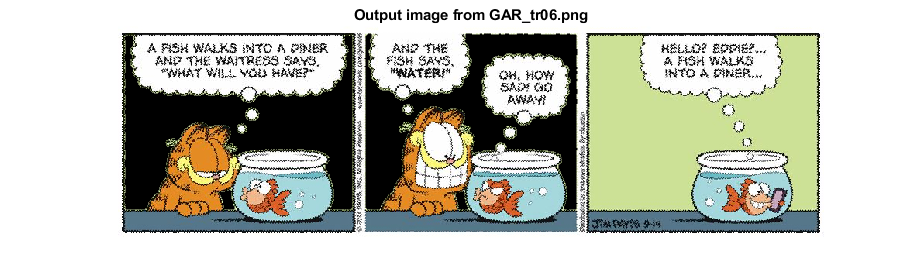


% Display the processed image
image_show_resize(outputImages{imageNumber});
title(['Output image from ' fileNames{imageNumber}],'Interpreter','none')